## Modulación Digital por Desplazamiento de Fase

En este sistema se envían señales con la misma frecuencia y amplitud, luego de módulo constante, pero con M posibles fases diferentes asociadas a los M símbolos del alfabeto utilizado. Cada uno de los símbolos se codificará n bits diferentes, siendo la relación entre n y M 𝑛 = log2 𝑀 En esta práctica prestaremos especial atención a la modulación QPSK, de cuatro niveles, cuya constelación es la que se muestra en la Figura 1.

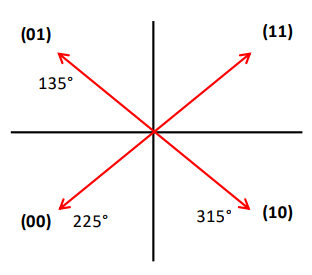

El nombre de QPSK viene de Quadrature Phase Shift Keying. La señal de cuatro niveles se construye como la superposición en fase y cuadratura de dos señales bifase BPSK (Binary Phase Shift Keying). 

En el paquete de funciones .m de Matlab que acompaña a la práctica se incluyen las de un modulador QPSK y de otro DQPSK, así como las de sus demoduladores correspondientes. Con la ayuda de estas funciones, el alumno deberá resolver los puntos restantes del apartado 2, comentando e interpretando los resultados que vaya obteniendo.

#### 2.1 Modulación QPSK

Compruebe el correcto funcionamiento de la función de modulación QPSK representando gráficamente mediante la función scatterplot el resultado de transmitir las cuatro secuencias binarias [1 1], [1 0], [0 1] y [0 0]. 

La función scatterplot representa los valores a su entrada en un plano complejo, por lo que es muy útil para ver gráficamente los símbolos producidos. Consulte la ayuda para conocer su funcionamiento. Asegúrese de que los símbolos producidos son coherentes con la constelación deseada. 

Asimismo, esta función es muy útil para analizar el efecto que tiene el ruido sobre la señal a transmitir, como veremos a continuación. 

%% =========================================================================
%% EJERCICIO 2.1: Modulación QPSK y Caracterización de Constelación
%% =========================================================================
clear; clc; close all;

parejas_bits = [1 1; 1 0; 0 1; 0 0];
txBits = reshape(parejas_bits', 1, []); 
xMod = moduladorQPSK(txBits);

% 1. Tabla de mapeo y símbolos
Bits_Transmitidos = ["1 1"; "1 0"; "0 1"; "0 0"];
I_Real            = real(xMod(:));
Q_Imag            = imag(xMod(:));
Modulo            = abs(xMod(:));
Fase_deg          = mod(angle(xMod(:)) * 180 / pi, 360);

tabla_ej21 = table(Bits_Transmitidos, I_Real, Q_Imag, Modulo, Fase_deg, ...
    'VariableNames', {'Bits', 'I', 'Q', 'Modulo', 'Fase_deg'});
disp(tabla_ej21);

    Bits     I     Q     Modulo    Fase_deg
    _____    __    __    ______    ________

    "1 1"     1     1    1.4142       45   
    "1 0"     1    -1    1.4142      315   
    "0 1"    -1     1    1.4142      135   
    "0 0"    -1    -1    1.4142      225   




% 2. Métricas de Capa Física y Espacio de Señales (ICAI Master Level)
d_min       = 2.0;                                   % Distancia euclídea mínima entre símbolos contiguos
Es          = mean(abs(xMod).^2);                   % Energía media de símbolo (Es = 2)
Eb          = Es / 2;                               % Energía media por bit (Eb = 1 -> 0 dB)
d_min_norm  = d_min / sqrt(Eb);                     % Distancia normalizada d_min / sqrt(Eb) = 2
PAPR_dB     = 10*log10(max(abs(xMod).^2) / Es);      % PAPR de la constelación (0 dB -> envolvente constante)
Eficiencia  = 2;                                    % bits/s/Hz teórica en banda base (Nyquist alpha=0)

tabla_metricas_21 = table(d_min, d_min_norm, Es, Eb, PAPR_dB, Eficiencia, ...
    'VariableNames', {'d_min', 'd_min_norm_Eb', 'Es', 'Eb', 'PAPR_dB', 'Eficiencia_bps_Hz'});
disp(tabla_metricas_21);

    d_min    d_min_norm_Eb    Es    Eb    PAPR_dB    Eficiencia_bps_Hz
    _____    _____________    __    __    _______    _________________

      2            2          2     1        0               2        



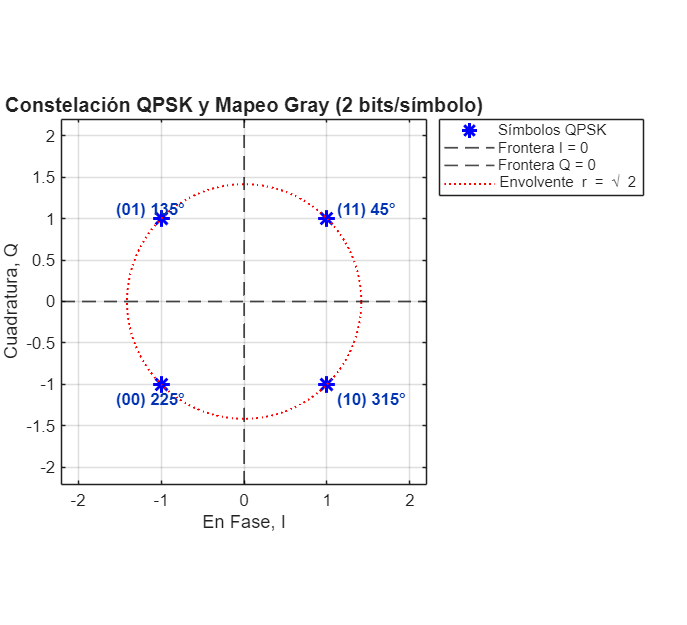


% 3. Gráfica de constelación en plano I-Q
figure('Color', 'w', 'Position', [150 150 550 500]);
ax = gca;
set(ax, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.85 0.85 0.85]);

plot(real(xMod), imag(xMod), 'b*', 'MarkerSize', 10, 'LineWidth', 1.8);
hold on; grid on; axis square;
axis([-2.2 2.2 -2.2 2.2]);

title('Constelación QPSK y Mapeo Gray (2 bits/símbolo)', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('En Fase, I', 'FontSize', 11);
ylabel('Cuadratura, Q', 'FontSize', 11);

xline(0, 'k--', 'LineWidth', 1);
yline(0, 'k--', 'LineWidth', 1);
th = linspace(0, 2*pi, 200);
plot(sqrt(2)*cos(th), sqrt(2)*sin(th), 'r:', 'LineWidth', 1.2);

etiquetas = {'(11) 45°', '(10) 315°', '(01) 135°', '(00) 225°'};
offset_x = [0.12,  0.12, -0.55, -0.55];
offset_y = [0.12, -0.18,  0.12, -0.18];
for idx = 1:length(xMod)
    text(real(xMod(idx)) + offset_x(idx), imag(xMod(idx)) + offset_y(idx), ...
        etiquetas{idx}, 'FontSize', 10, 'FontWeight', 'bold', 'Color', [0 0.2 0.7]);
end

legend({'Símbolos QPSK', 'Frontera I = 0', 'Frontera Q = 0', 'Envolvente r = \surd 2'}, ...
    'Location', 'northeastoutside', 'Color', 'w');

#### 2.2 modulación QPSK con ruido

Genere un vector de bits aleatorios y modúlelos en QPSK. Sobre el vector de símbolos modulados, añada ruido blanco gaussiano AWGN para simular el efecto del ruido presente en el receptor; la función awgn le será de utilidad. 

Haga una representación gráfica utilizando scatterplot al añadir un ruido con 5 dB, 10 dB y 15 dB de relación señal a ruido, SNR_dB. Muestre los gráficos obtenidos y coméntelos. ¿Cómo afecta el ruido a la generación de bits erróneos?

%% =========================================================================
%% EJERCICIO 2.2: QPSK en Canal AWGN con Métrica EVM
%% =========================================================================
Nbits = 4000;
rng(42);
txBits_rand = randi([0 1], 1, Nbits);
xMod_rand = moduladorQPSK(txBits_rand);

k = log2(4);
SNR_vect_dB = [5, 10, 15];
simb_ideales = [1+1j, -1+1j, -1-1j, 1-1j];

EbN0_dB_calc    = (SNR_vect_dB - 10*log10(k))';
EbN0_lin        = 10.^(EbN0_dB_calc / 10);
sigma_ruido     = sqrt(10.^(-SNR_vect_dB(:) / 10));
margen_frontera = 1.0 ./ sigma_ruido;

% Métricas avanzadas: EVM y Probabilidad de Error de Símbolo vs Bit
EVM_porc        = (1 ./ sqrt(10.^(SNR_vect_dB(:)/10))) * 100;
EVM_dB          = -SNR_vect_dB(:);
BER_teorica     = qfunc(sqrt(2 * EbN0_lin));
SER_teorica     = 2*BER_teorica - BER_teorica.^2;   % Ps exacta en QPSK

tabla_ej22 = table(SNR_vect_dB', EbN0_dB_calc, sigma_ruido, margen_frontera, ...
    EVM_porc, BER_teorica, SER_teorica, ...
    'VariableNames', {'SNR_dB', 'EbN0_dB', 'Sigma_Ruido', 'Margen_d_sigma', ...
    'EVM_porc', 'BER_Teorica', 'SER_Teorica'});
disp(tabla_ej22);

    SNR_dB    EbN0_dB    Sigma_Ruido    Margen_d_sigma    EVM_porc    BER_Teorica    SER_Teorica
    ______    _______    ___________    ______________    ________    ___________    ___________

       5      1.9897       0.56234          1.7783         56.234       0.037679       0.073938 
      10      6.9897       0.31623          3.1623         31.623      0.0007827      0.0015648 
      15       11.99       0.17783          5.6234         17.783      9.361e-09     1.8722e-08 



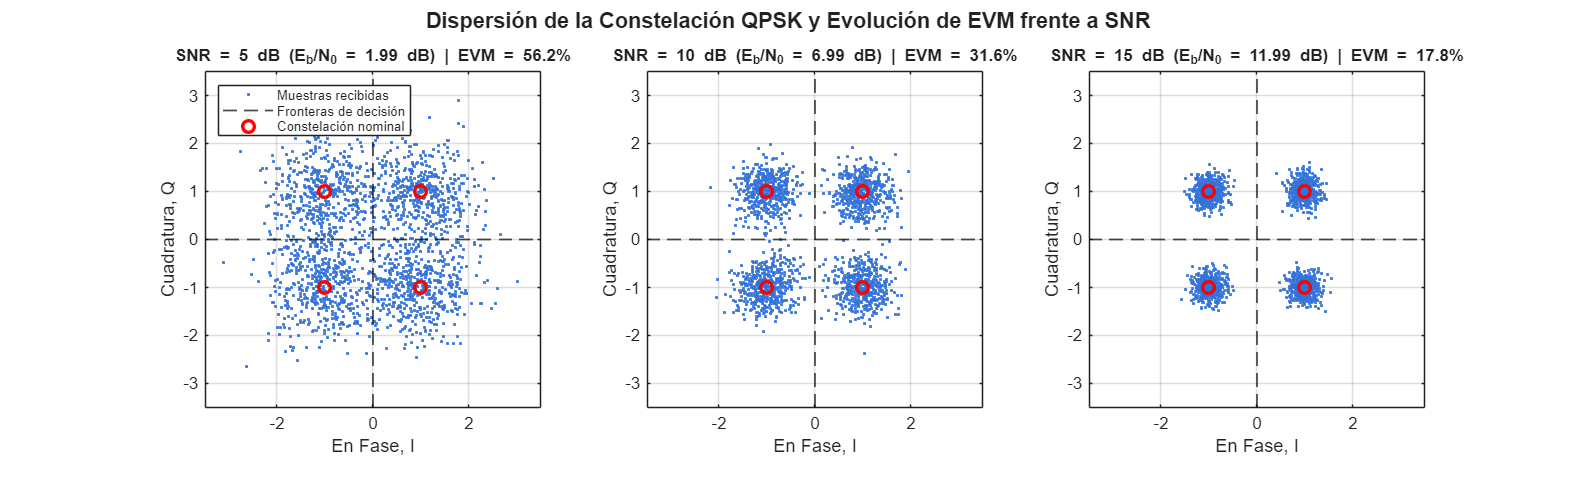


% Subplots 1x3 ya validados
figure('Color', 'w', 'Position', [80 200 1350 420]);
for i = 1:length(SNR_vect_dB)
    snr_i = SNR_vect_dB(i);
    rx_noisy = awgn(xMod_rand, snr_i, 'measured');

    subplot(1, 3, i);
    ax = gca;
    set(ax, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.85 0.85 0.85]);

    plot(real(rx_noisy), imag(rx_noisy), '.', 'Color', [0.2 0.45 0.85], 'MarkerSize', 5);
    hold on; grid on; axis square;
    axis([-3.5 3.5 -3.5 3.5]);

    xline(0, 'k--', 'LineWidth', 1.1);
    yline(0, 'k--', 'LineWidth', 1.1);
    plot(real(simb_ideales), imag(simb_ideales), 'ro', 'MarkerSize', 7, 'LineWidth', 2);

    title(sprintf('SNR = %d dB (E_b/N_0 = %.2f dB) | EVM = %.1f%%', ...
        snr_i, EbN0_dB_calc(i), EVM_porc(i)), 'FontSize', 10, 'FontWeight', 'bold');
    xlabel('En Fase, I'); ylabel('Cuadratura, Q');

    if i == 1
        legend({'Muestras recibidas', 'Fronteras de decisión', '', 'Constelación nominal'}, ...
            'Location', 'northwest', 'FontSize', 8, 'Color', 'w');
    end
end
sgtitle('Dispersión de la Constelación QPSK y Evolución de EVM frente a SNR', ...
    'FontSize', 13, 'FontWeight', 'bold');

#### 2.3 Cadena de modulación-demodulación QPSK y DQPSK 

Empleando el vector de bits aleatorios del ejercicio anterior, genere una señal modulada en QPSK y a continuación demodúlela con la función del demodulador QPSK. Compruebe que en ausencia de ruido los bits recibidos son idénticos a los transmitidos, y por tanto BER = 0. Realice el mismo ejercicio, pero con modulación y demodulación diferencial DQPSK.

%% =========================================================================
%% EJERCICIO 2.3: Cadena Completa QPSK vs DQPSK (Canal Ideal)
%% =========================================================================

% Rama QPSK Coherente
xMod_QPSK   = moduladorQPSK(txBits_rand);
rxBits_QPSK = demoduladorQPSK(xMod_QPSK);
numErr_QPSK = sum(abs(txBits_rand - rxBits_QPSK));
BER_QPSK    = numErr_QPSK / length(txBits_rand);

% Rama DQPSK Diferencial
xMod_DQPSK   = moduladorDQPSK(txBits_rand);
rxBits_DQPSK = demoduladorDQPSK(xMod_DQPSK);
numErr_DQPSK = sum(abs(txBits_rand - rxBits_DQPSK));
BER_DQPSK    = numErr_DQPSK / length(txBits_rand);

% Tabla en formato string
Esquema           = ["QPSK Coherente"; "DQPSK Diferencial"];
Bits_Tx           = [length(txBits_rand); length(txBits_rand)];
Errores_Bit       = [numErr_QPSK; numErr_DQPSK];
BER_Obtenida      = [BER_QPSK; BER_DQPSK];
Condicion_Canal   = ["Canal ideal (sin ruido)"; "Canal ideal (sin ruido)"];
Sincronizacion    = ["Bucle de Costas / PLL obligatorio"; "No coherente (detección de fase relativa)"];

tabla_ej23 = table(Esquema, Bits_Tx, Errores_Bit, BER_Obtenida, Condicion_Canal, Sincronizacion, ...
    'VariableNames', {'Esquema', 'Bits_Tx', 'Errores', 'BER', 'Canal', 'Requisito_Sincronismo'});
disp(tabla_ej23);

          Esquema          Bits_Tx    Errores    BER              Canal                         Requisito_Sincronismo           
    ___________________    _______    _______    ___    _________________________    ___________________________________________

    "QPSK Coherente"        4000         0        0     "Canal ideal (sin ruido)"    "Bucle de Costas / PLL obligatorio"        
    "DQPSK Diferencial"     4000         0        0     "Canal ideal (sin ruido)"    "No coherente (detección de fase relativa)"



**2.4 Curvas de BER frente a EbNo_dB para QPSK y DQPSK**

Simule y represente gráficamente el comportamiento de la modulación QPSK en términos de BER en función de valores crecientes de EbNo_dB, cuando el ruido es blanco y gaussiano (AWGN). Utilice los valores de EbNo_dB = -5:2:10. La gráfica deberá emplear ejes semilogarítmicos. En la misma gráfica superponga la curva teórica de BER frente a EbNo_dB. Repita lo anterior para el sistema de modulación DQPSK, y compare las prestaciones de BER frente a EbNo entre ambos sistemas. En DQPSK la probabilidad de error teórica es Pb = 1.13·Q(√(1.2·EbN0)).

%% =========================================================================
%% EJERCICIO 2.4: BER frente a SNR para QPSK y DQPSK
%% =========================================================================
EbN0_dB_vect = -5:2:10;
Nbits_BER    = 4e5;

[BER_sim_QPSK,  BER_teor_QPSK, SNR_dB_vect] = simular_BER_PSK('QPSK',  EbN0_dB_vect, Nbits_BER, 0);
[BER_sim_DQPSK, BER_teor_DQPSK]             = simular_BER_PSK('DQPSK', EbN0_dB_vect, Nbits_BER, 0);

% Curvas teóricas con resolución fina
SNR_fino  = SNR_dB_vect(1):0.1:SNR_dB_vect(end);
EbN0_fino = 10.^((SNR_fino - 10*log10(2)) / 10);
teor_QPSK_fino  = qfunc(sqrt(2*EbN0_fino));
teor_DQPSK_fino = 1.13*qfunc(sqrt(1.2*EbN0_fino));
teor_QPSK_fino(teor_QPSK_fino < 1e-5)   = NaN;
teor_DQPSK_fino(teor_DQPSK_fino < 1e-5) = NaN;

% 1. Resultados punto a punto
Ratio_BER = BER_sim_DQPSK ./ BER_sim_QPSK;
tabla_ej24 = table(SNR_dB_vect', EbN0_dB_vect', BER_sim_QPSK', BER_teor_QPSK', ...
    BER_sim_DQPSK', BER_teor_DQPSK', Ratio_BER', ...
    'VariableNames', {'SNR_dB', 'EbN0_dB', 'BER_QPSK_sim', 'BER_QPSK_teor', ...
    'BER_DQPSK_sim', 'BER_DQPSK_teor', 'BER_DQPSK_div_QPSK'});
disp(tabla_ej24);

    SNR_dB     EbN0_dB    BER_QPSK_sim    BER_QPSK_teor    BER_DQPSK_sim    BER_DQPSK_teor    BER_DQPSK_div_QPSK
    _______    _______    ____________    _____________    _____________    ______________    __________________

    -1.9897      -5          0.21275          0.21323         0.33175           0.30391             1.5593      
     0.0103      -3          0.15867          0.15837         0.27015           0.24749             1.7026      
     2.0103      -1          0.10359          0.10376         0.19978           0.18583             1.9285      
     4.0103       1          0.05635         0.056282         0.13092           0.12375             2.3233      
     6.0103       3         0.022748         0.022878         0.07179          0.06


% 2. SNR necesaria para cada BER objetivo y penalización de DQPSK
BER_obj   = [1e-1; 1e-2; 1e-3];
SNR_QPSK  = arrayfun(@(b) SNR_para_BER(SNR_dB_vect, BER_sim_QPSK,  b), BER_obj);
SNR_DQPSK = arrayfun(@(b) SNR_para_BER(SNR_dB_vect, BER_sim_DQPSK, b), BER_obj);
tabla_SNR_24 = table(BER_obj, SNR_QPSK, SNR_DQPSK, SNR_DQPSK - SNR_QPSK, ...
    'VariableNames', {'BER_objetivo', 'SNR_QPSK_dB', 'SNR_DQPSK_dB', 'Penalizacion_DQPSK_dB'});
disp(tabla_SNR_24);

    BER_objetivo    SNR_QPSK_dB    SNR_DQPSK_dB    Penalizacion_DQPSK_dB
    ____________    ___________    ____________    _____________________

         0.1          2.1262          4.9071              2.7808        
        0.01          7.2604          9.7745              2.5142        
       0.001           9.725             NaN                 NaN        



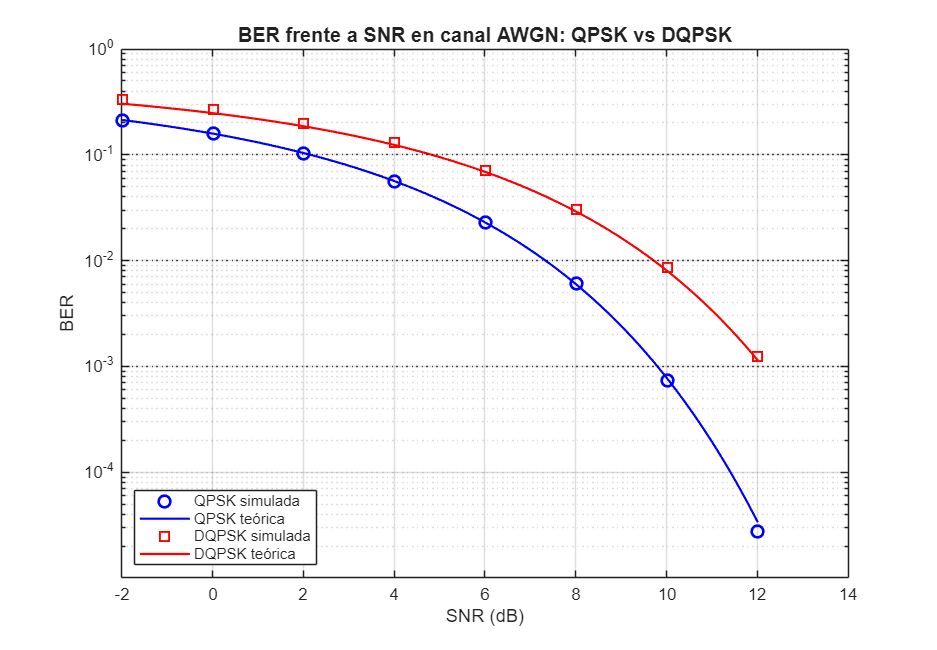


% 3. BER frente a SNR
figure('Color', 'w', 'Position', [150 150 750 520]);
semilogy(SNR_dB_vect, BER_sim_QPSK,  'bo', 'MarkerSize', 7, 'LineWidth', 1.6); hold on;
semilogy(SNR_fino,    teor_QPSK_fino,  'b-', 'LineWidth', 1.3);
semilogy(SNR_dB_vect, BER_sim_DQPSK, 'rs', 'MarkerSize', 7, 'LineWidth', 1.6);
semilogy(SNR_fino,    teor_DQPSK_fino, 'r-', 'LineWidth', 1.3);
for b = BER_obj'
    yline(b, 'k:', 'HandleVisibility', 'off');
end
grid on; ylim([1e-5 1]);
title('BER frente a SNR en canal AWGN: QPSK vs DQPSK', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('SNR (dB)', 'FontSize', 11);
ylabel('BER', 'FontSize', 11);
legend({'QPSK simulada', 'QPSK teórica', 'DQPSK simulada', 'DQPSK teórica'}, ...
    'Location', 'southwest');

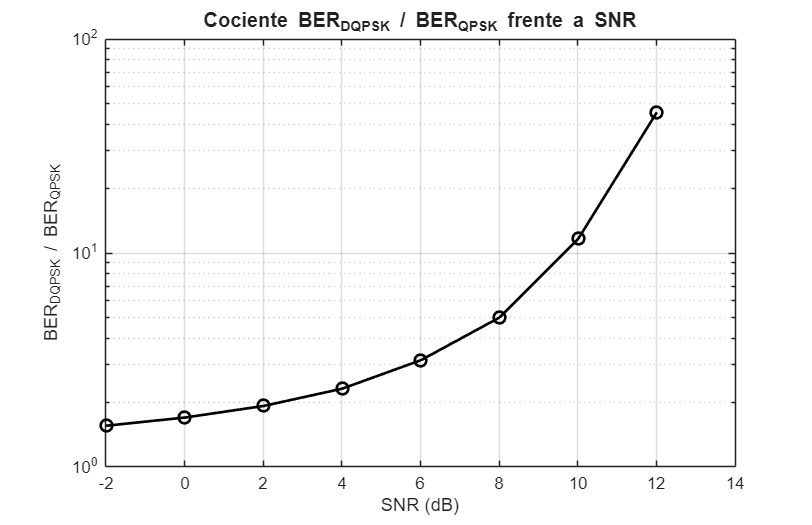


% 4. Cociente BER_DQPSK / BER_QPSK a lo largo de la curva
figure('Color', 'w', 'Position', [150 150 650 420]);
semilogy(SNR_dB_vect, Ratio_BER, 'ko-', 'LineWidth', 1.6, 'MarkerSize', 7);
grid on;
title('Cociente BER_{DQPSK} / BER_{QPSK} frente a SNR', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('SNR (dB)', 'FontSize', 11);
ylabel('BER_{DQPSK} / BER_{QPSK}', 'FontSize', 11);

**2.5 Influencia de la rotación de la fase o error de fase en recepción**

Modifique el código del ejercicio anterior incluyendo en el canal, además de AWGN, una rotación de fase, por ejemplo 10-30º, tanto para QPSK como para DQPSK. Esta rotación puede ser el resultado de un offset de fase en el oscilador local del receptor. Obtenga las curvas de BER en función de EbNo_dB, e interprete y justifique los resultados obtenidos.

%% =========================================================================
%% EJERCICIO 2.5: Influencia del Error de Fase en Recepción
%% =========================================================================
offsets_deg = [0 10 20 30];
nOff        = length(offsets_deg);
EbN0_dB_25  = -5:1:14;              % Rango ampliado para llegar a BER = 1e-4
Nbits_25    = 1e6;
colores     = lines(nOff);

BER_rot_QPSK  = zeros(nOff, length(EbN0_dB_25));
BER_rot_DQPSK = zeros(nOff, length(EbN0_dB_25));
BER_rot_teor  = zeros(nOff, length(EbN0_dB_25));
EbN0_lin_25   = 10.^(EbN0_dB_25 / 10);
for i = 1:nOff
    phi = offsets_deg(i);
    [BER_rot_QPSK(i,:), ~, SNR_dB_25] = simular_BER_PSK('QPSK',  EbN0_dB_25, Nbits_25, phi);
    BER_rot_DQPSK(i,:)                = simular_BER_PSK('DQPSK', EbN0_dB_25, Nbits_25, phi);
    % QPSK con rotación phi: distancias (cos phi - sin phi) y (cos phi + sin phi) a las fronteras
    BER_rot_teor(i,:) = 0.5*( qfunc(sqrt(2*EbN0_lin_25)*(cosd(phi) - sind(phi))) + ...
                              qfunc(sqrt(2*EbN0_lin_25)*(cosd(phi) + sind(phi))) );
end
BER_rot_teor(BER_rot_teor < 1e-5) = NaN;

% 1. SNR necesaria para BER = 1e-2, 1e-3, 1e-4
BER_obj_25 = [1e-2 1e-3 1e-4];
SNRreq_Q = zeros(nOff, 3);
SNRreq_D = zeros(nOff, 3);
for i = 1:nOff
    for j = 1:3
        SNRreq_Q(i,j) = SNR_para_BER(SNR_dB_25, BER_rot_QPSK(i,:),  BER_obj_25(j));
        SNRreq_D(i,j) = SNR_para_BER(SNR_dB_25, BER_rot_DQPSK(i,:), BER_obj_25(j));
    end
end
Perdida_asint_dB = -20*log10(cosd(offsets_deg') - sind(offsets_deg'));

tabla_ej25_QPSK = array2table([offsets_deg', SNRreq_Q, SNRreq_Q - SNRreq_Q(1,:), Perdida_asint_dB], ...
    'VariableNames', {'phi_deg', 'SNR_1e2', 'SNR_1e3', 'SNR_1e4', ...
    'Penal_1e2', 'Penal_1e3', 'Penal_1e4', 'Penal_asint'});
tabla_ej25_DQPSK = array2table([offsets_deg', SNRreq_D, SNRreq_D - SNRreq_D(1,:)], ...
    'VariableNames', {'phi_deg', 'SNR_1e2', 'SNR_1e3', 'SNR_1e4', ...
    'Penal_1e2', 'Penal_1e3', 'Penal_1e4'});
tabla_ej25_comp = array2table([offsets_deg', SNRreq_Q - SNRreq_D], ...
    'VariableNames', {'phi_deg', 'SNR_QPSK_menos_DQPSK_1e2', 'SNR_QPSK_menos_DQPSK_1e3', ...
    'SNR_QPSK_menos_DQPSK_1e4'});
disp('QPSK:');  disp(tabla_ej25_QPSK);

QPSK:
    phi_deg    SNR_1e2    SNR_1e3    SNR_1e4    Penal_1e2    Penal_1e3    Penal_1e4    Penal_asint
    _______    _______    _______    _______    _________    _________    _________    ___________

       0       7.3027     9.7679     11.368           0            0            0             0   
      10       8.2034     11.006     12.854      0.9006       1.2382        1.486        1.8179   
      20        10.73      13.62     15.428      3.4275       3.8517       4.0601        4.4707   
      30       14.976        NaN        NaN      7.6731          NaN          NaN        8.7298   



disp('DQPSK:'); disp(tabla_ej25_DQPSK);

DQPSK:
    phi_deg    SNR_1e2    SNR_1e3    SNR_1e4    Penal_1e2     Penal_1e3    Penal_1e4
    _______    _______    _______    _______    __________    _________    _________

       0       9.8048     12.169      13.81              0            0            0
      10       9.8011     12.219     13.765     -0.0036293     0.050111    -0.045142
      20       9.7816     12.208     13.693      -0.023135     0.039044     -0.11666
      30       9.7879     12.175     13.724      -0.016885    0.0055741    -0.085721



disp('Diferencia de SNR necesaria (>0: DQPSK necesita menos SNR):'); disp(tabla_ej25_comp);

Diferencia de SNR necesaria (>0: DQPSK necesita menos SNR):
    phi_deg    SNR_QPSK_menos_DQPSK_1e2    SNR_QPSK_menos_DQPSK_1e3    SNR_QPSK_menos_DQPSK_1e4
    _______    ________________________    ________________________    ________________________

       0                -2.502                     -2.4014                      -2.4421        
      10               -1.5978                     -1.2133                     -0.91092        
      20               0.94861                      1.4113                       1.7346        
      30                 5.188                         NaN                          NaN        



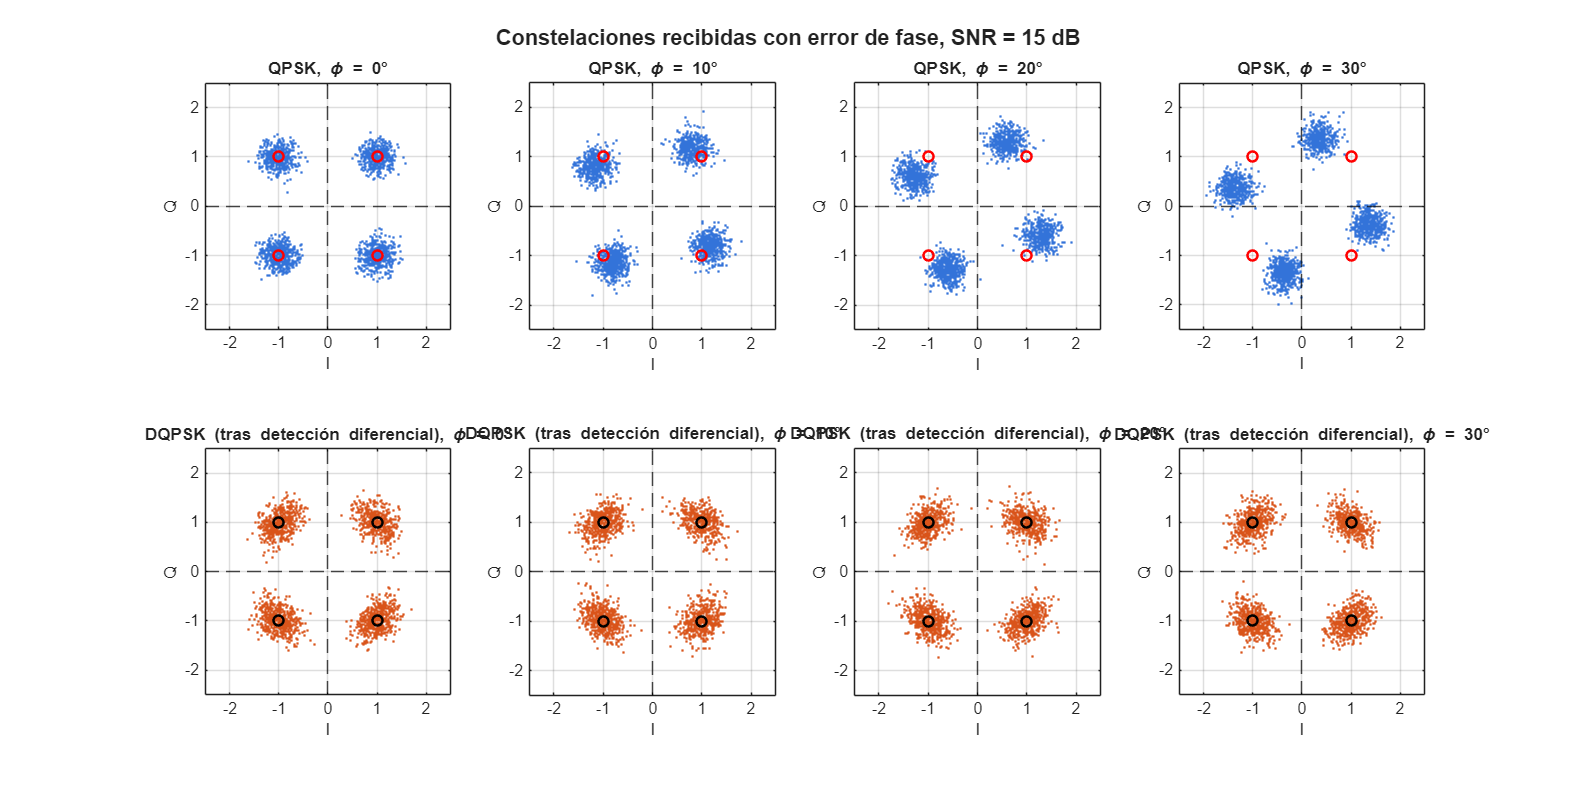


% 2. Constelaciones recibidas con error de fase (SNR = 15 dB)
%    Fila superior: QPSK. Fila inferior: símbolo diferencial que ve el decisor DQPSK
SNR_const  = 15;
bits_const = randi([0 1], 1, 4000);
xQ_c = moduladorQPSK(bits_const);
xD_c = moduladorDQPSK(bits_const);
figure('Color', 'w', 'Position', [50 80 1400 700]);
for i = 1:nOff
    rot = exp(1j*offsets_deg(i)*pi/180);
    rQ  = awgn(xQ_c, SNR_const, 'measured') * rot;
    rD  = awgn(xD_c, SNR_const, 'measured') * rot;
    zD  = rD(2:end) ./ exp(1j*angle(rD(1:end-1)));

    subplot(2, nOff, i);
    plot(real(rQ), imag(rQ), '.', 'Color', [0.2 0.45 0.85], 'MarkerSize', 4); hold on;
    plot(real(simb_ideales), imag(simb_ideales), 'ro', 'MarkerSize', 6, 'LineWidth', 1.5);
    xline(0, 'k--'); yline(0, 'k--');
    grid on; axis square; axis([-2.5 2.5 -2.5 2.5]);
    title(sprintf('QPSK, \\phi = %d°', offsets_deg(i)), 'FontWeight', 'bold');
    xlabel('I'); ylabel('Q');

    subplot(2, nOff, nOff + i);
    plot(real(zD), imag(zD), '.', 'Color', [0.85 0.33 0.1], 'MarkerSize', 4); hold on;
    plot(real(simb_ideales), imag(simb_ideales), 'ko', 'MarkerSize', 6, 'LineWidth', 1.5);
    xline(0, 'k--'); yline(0, 'k--');
    grid on; axis square; axis([-2.5 2.5 -2.5 2.5]);
    title(sprintf('DQPSK (tras detección diferencial), \\phi = %d°', offsets_deg(i)), 'FontWeight', 'bold');
    xlabel('I'); ylabel('Q');
end
sgtitle(sprintf('Constelaciones recibidas con error de fase, SNR = %d dB', SNR_const), ...
    'FontSize', 13, 'FontWeight', 'bold');

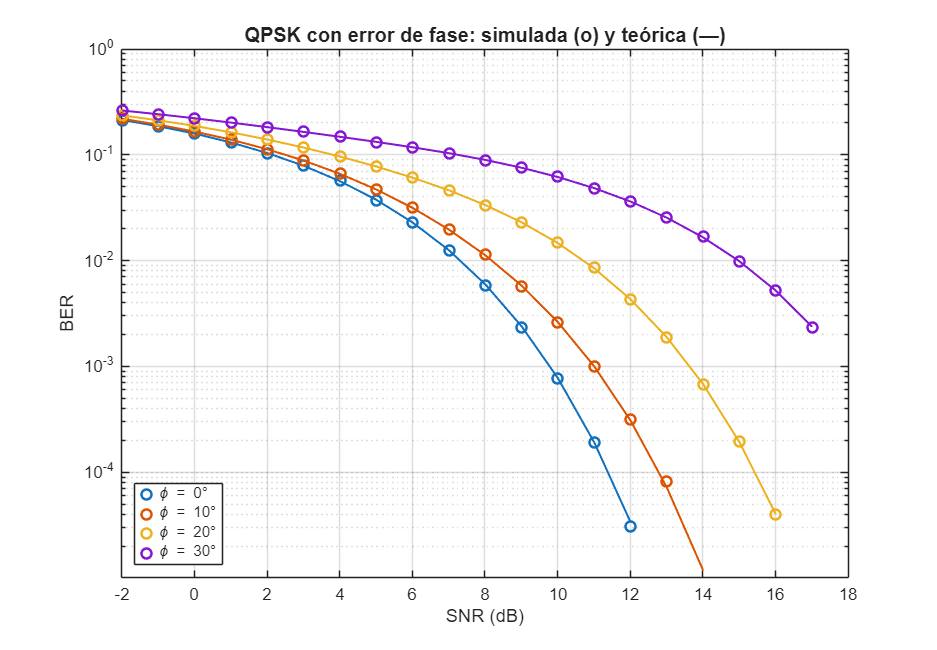


% 3. QPSK: BER frente a SNR para cada error de fase
figure('Color', 'w', 'Position', [150 150 750 520]);
for i = 1:nOff
    semilogy(SNR_dB_25, BER_rot_QPSK(i,:), 'o', 'Color', colores(i,:), 'LineWidth', 1.5); hold on;
    semilogy(SNR_dB_25, BER_rot_teor(i,:), '-', 'Color', colores(i,:), 'LineWidth', 1.2, ...
        'HandleVisibility', 'off');
end
grid on; ylim([1e-5 1]);
title('QPSK con error de fase: simulada (o) y teórica (—)', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('SNR (dB)', 'FontSize', 11); ylabel('BER', 'FontSize', 11);
legend(compose('\\phi = %d°', offsets_deg), 'Location', 'southwest');

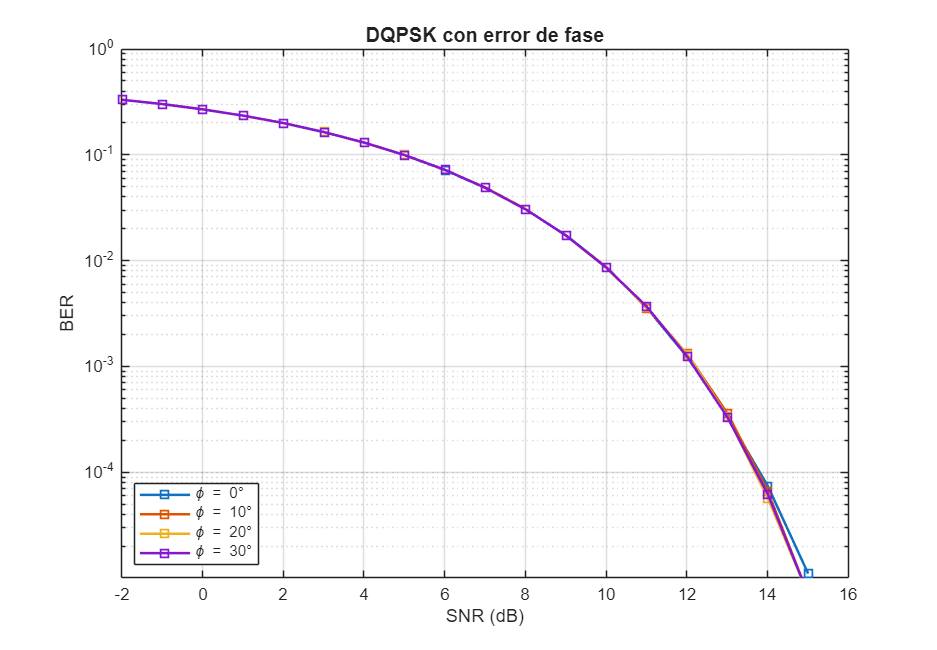


% 4. DQPSK: BER frente a SNR para cada error de fase
figure('Color', 'w', 'Position', [150 150 750 520]);
for i = 1:nOff
    semilogy(SNR_dB_25, BER_rot_DQPSK(i,:), 's-', 'Color', colores(i,:), 'LineWidth', 1.5); hold on;
end
grid on; ylim([1e-5 1]);
title('DQPSK con error de fase', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('SNR (dB)', 'FontSize', 11); ylabel('BER', 'FontSize', 11);
legend(compose('\\phi = %d°', offsets_deg), 'Location', 'southwest');

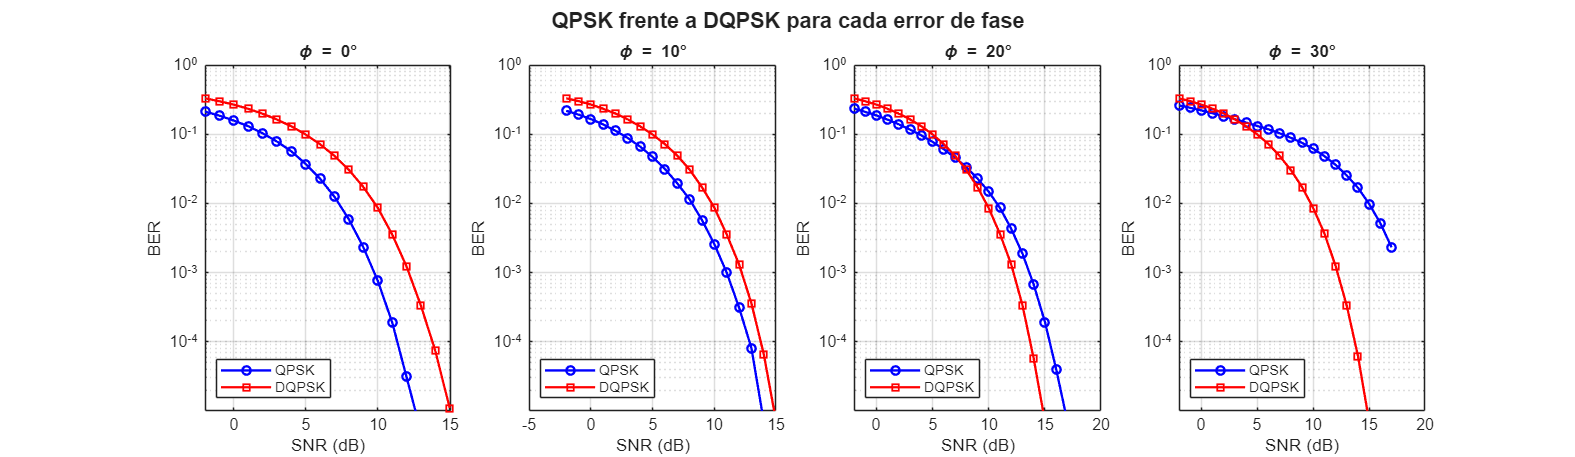


% 5. Comparación QPSK vs DQPSK para cada error de fase
figure('Color', 'w', 'Position', [40 200 1450 420]);
for i = 1:nOff
    subplot(1, nOff, i);
    semilogy(SNR_dB_25, BER_rot_QPSK(i,:),  'bo-', 'LineWidth', 1.4, 'MarkerSize', 5); hold on;
    semilogy(SNR_dB_25, BER_rot_DQPSK(i,:), 'rs-', 'LineWidth', 1.4, 'MarkerSize', 5);
    grid on; ylim([1e-5 1]);
    title(sprintf('\\phi = %d°', offsets_deg(i)), 'FontWeight', 'bold');
    xlabel('SNR (dB)'); ylabel('BER');
    legend({'QPSK', 'DQPSK'}, 'Location', 'southwest');
end
sgtitle('QPSK frente a DQPSK para cada error de fase', 'FontSize', 13, 'FontWeight', 'bold');


% 6. BER frente al error de fase con SNR fija = 10 dB
SNR_fija      = 10;
theta_barrido = 0:2.5:45;
BER_th_Q      = zeros(size(theta_barrido));
BER_th_D      = zeros(size(theta_barrido));
for i = 1:length(theta_barrido)
    BER_th_Q(i) = simular_BER_PSK('QPSK',  SNR_fija - 10*log10(2), 2e5, theta_barrido(i));
    BER_th_D(i) = simular_BER_PSK('DQPSK', SNR_fija - 10*log10(2), 2e5, theta_barrido(i));
end
EbN0_fija = 10^((SNR_fija - 10*log10(2))/10);
BER_th_teor = 0.5*( qfunc(sqrt(2*EbN0_fija)*(cosd(theta_barrido) - sind(theta_barrido))) + ...
                    qfunc(sqrt(2*EbN0_fija)*(cosd(theta_barrido) + sind(theta_barrido))) );
theta_cruce_sim = interp1(log10(BER_th_Q) - log10(BER_th_D), theta_barrido, 0);
fprintf('Con SNR = %d dB, QPSK pasa a ser peor que DQPSK a partir de phi = %.1f°\n', ...
    SNR_fija, theta_cruce_sim);

Con SNR = 10 dB, QPSK pasa a ser peor que DQPSK a partir de phi = 16.9°


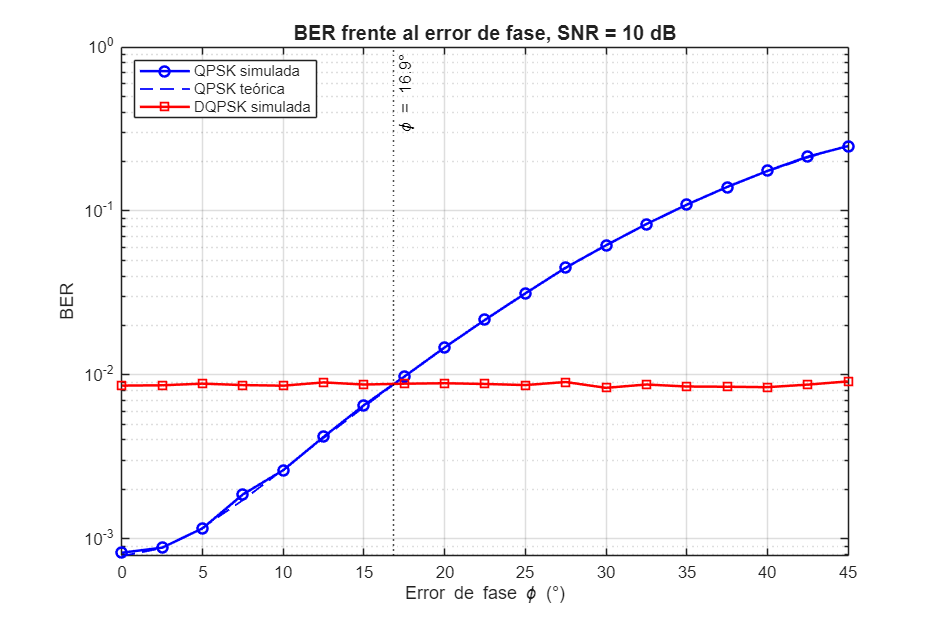


figure('Color', 'w', 'Position', [150 150 750 500]);
semilogy(theta_barrido, BER_th_Q,    'bo-', 'LineWidth', 1.5); hold on;
semilogy(theta_barrido, BER_th_teor, 'b--', 'LineWidth', 1.1);
semilogy(theta_barrido, BER_th_D,    'rs-', 'LineWidth', 1.5);
xline(theta_cruce_sim, 'k:', sprintf('\\phi = %.1f°', theta_cruce_sim));
grid on;
title(sprintf('BER frente al error de fase, SNR = %d dB', SNR_fija), 'FontSize', 12, 'FontWeight', 'bold');
xlabel('Error de fase \phi (°)', 'FontSize', 11); ylabel('BER', 'FontSize', 11);
legend({'QPSK simulada', 'QPSK teórica', 'DQPSK simulada'}, 'Location', 'northwest');


% 7. SNR necesaria para BER = 1e-3 en función del error de fase
theta_fino  = 0:0.5:30;
SNR_f       = -2:0.05:30;
EbN0_f      = 10.^((SNR_f - 10*log10(2)) / 10);
SNRreq_teor = zeros(size(theta_fino));
for i = 1:length(theta_fino)
    t = theta_fino(i);
    ber_t = 0.5*( qfunc(sqrt(2*EbN0_f)*(cosd(t) - sind(t))) + qfunc(sqrt(2*EbN0_f)*(cosd(t) + sind(t))) );
    SNRreq_teor(i) = SNR_para_BER(SNR_f, ber_t, 1e-3);
end
SNRreq_DQPSK_teor = SNR_para_BER(SNR_f, 1.13*qfunc(sqrt(1.2*EbN0_f)), 1e-3);
theta_cruce_teor  = interp1(SNRreq_teor, theta_fino, SNRreq_DQPSK_teor);
fprintf('Para BER = 1e-3, QPSK necesita más SNR que DQPSK a partir de phi = %.1f° (teórico)\n', ...
    theta_cruce_teor);

Para BER = 1e-3, QPSK necesita más SNR que DQPSK a partir de phi = 14.7° (teórico)


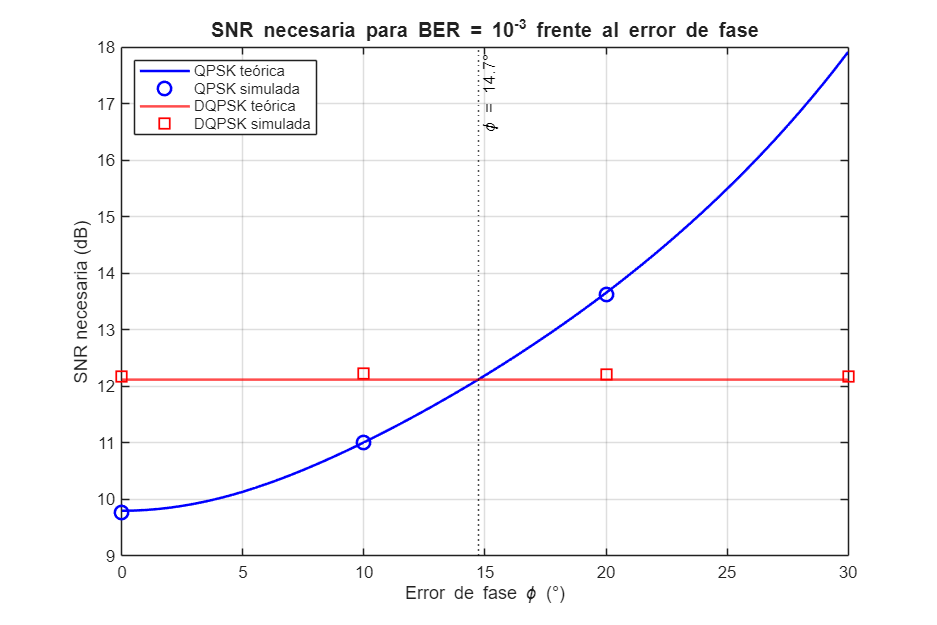


figure('Color', 'w', 'Position', [150 150 750 500]);
plot(theta_fino, SNRreq_teor, 'b-', 'LineWidth', 1.5); hold on;
plot(offsets_deg, SNRreq_Q(:,2), 'bo', 'MarkerSize', 8, 'LineWidth', 1.5);
yline(SNRreq_DQPSK_teor, 'r-', 'LineWidth', 1.5);
plot(offsets_deg, SNRreq_D(:,2), 'rs', 'MarkerSize', 8, 'LineWidth', 1.5);
xline(theta_cruce_teor, 'k:', sprintf('\\phi = %.1f°', theta_cruce_teor));
grid on;
title('SNR necesaria para BER = 10^{-3} frente al error de fase', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('Error de fase \phi (°)', 'FontSize', 11); ylabel('SNR necesaria (dB)', 'FontSize', 11);
legend({'QPSK teórica', 'QPSK simulada', 'DQPSK teórica', 'DQPSK simulada'}, 'Location', 'northwest');

**3.1. Curvas de BER frente a EbNo_dB para QAM y APSK**

Con ayuda de las funciones que se acompañan, represente las curvas simuladas de BER frente a EbNo_dB para los sistemas de modulación 4-QAM, 16-QAM, 64-QAM, 256-QAM, 16 APSK y 32 APSK. Para el caso de 16 APSK el radio del segundo círculo será 2.5 veces el del primero. Para 32 APSK la relación de los radios segundo y tercero con respecto al primero será 2,5 y 4,3 respectivamente. Analice de manera cuantitativa los resultados obtenidos.

%% =========================================================================
%% EJERCICIO 3.1: BER frente a SNR para M-QAM y APSK
%% =========================================================================
EbN0_dB_3  = 0:2:24;
Modulacion = ["4-QAM"; "16-QAM"; "64-QAM"; "256-QAM"; "16-APSK"; "32-APSK"];
Bits_simb  = [2; 4; 6; 8; 4; 5];
M_QAM      = [4 16 64 256];
M_16APSK   = [4 12];      R_16APSK = [1 2.5];
M_32APSK   = [4 12 16];   R_32APSK = [1 2.5 4.3];

BER_3       = zeros(6, length(EbN0_dB_3));
BER_QAMteor = zeros(4, length(EbN0_dB_3));
for i = 1:4
    [BER_3(i,:), BER_QAMteor(i,:)] = BER_m_ary_QAM(M_QAM(i), EbN0_dB_3);
end
BER_3(5,:) = BER_APSK(M_16APSK, R_16APSK, EbN0_dB_3);
BER_3(6,:) = BER_APSK(M_32APSK, R_32APSK, EbN0_dB_3);
SNR_3      = EbN0_dB_3 + 10*log10(Bits_simb);          % Una fila por modulación

% 1. Métricas: SNR necesaria, distancia mínima normalizada y PAPR
consts = {qammod((0:3)', 4), qammod((0:15)', 16), qammod((0:63)', 64), qammod((0:255)', 256), ...
          apskmod((0:15)', M_16APSK, R_16APSK), apskmod((0:31)', M_32APSK, R_32APSK)};
SNR_1e2 = zeros(6,1); SNR_1e3 = zeros(6,1); d_min_norm_Eb = zeros(6,1); PAPR_dB = zeros(6,1);
for i = 1:6
    c  = consts{i};
    Es = mean(abs(c).^2);
    D  = abs(c - c.');  D(D == 0) = Inf;
    d_min_norm_Eb(i) = min(D(:)) / sqrt(Es / Bits_simb(i));
    PAPR_dB(i)       = 10*log10(max(abs(c).^2) / Es);
    SNR_1e2(i)       = SNR_para_BER(SNR_3(i,:), BER_3(i,:), 1e-2);
    SNR_1e3(i)       = SNR_para_BER(SNR_3(i,:), BER_3(i,:), 1e-3);
end
tabla_ej31 = table(Modulacion, Bits_simb, SNR_1e2, SNR_1e3, d_min_norm_Eb, PAPR_dB, ...
    'VariableNames', {'Modulacion', 'Bits_simbolo', 'SNR_dB_BER1e2', 'SNR_dB_BER1e3', ...
    'd_min_norm_Eb', 'PAPR_dB'});
disp(tabla_ej31);

    Modulacion    Bits_simbolo    SNR_dB_BER1e2    SNR_dB_BER1e3    d_min_norm_Eb    PAPR_dB
    __________    ____________    _____________    _____________    _____________    _______

    "4-QAM"            2             7.2849           9.5612                 2            0 
    "16-QAM"           4             13.791           16.494            1.2649       2.5527 
    "64-QAM"           6             19.813           22.352           0.75593       3.6798 
    "256-QAM"          8             25.392           28.557           0.43386       4.2276 
    "16-APSK"          4             14.294           16.645            1.1648       1.0237 
    "32-APSK"          5             17.079            20.04           0.84548       1.9824 



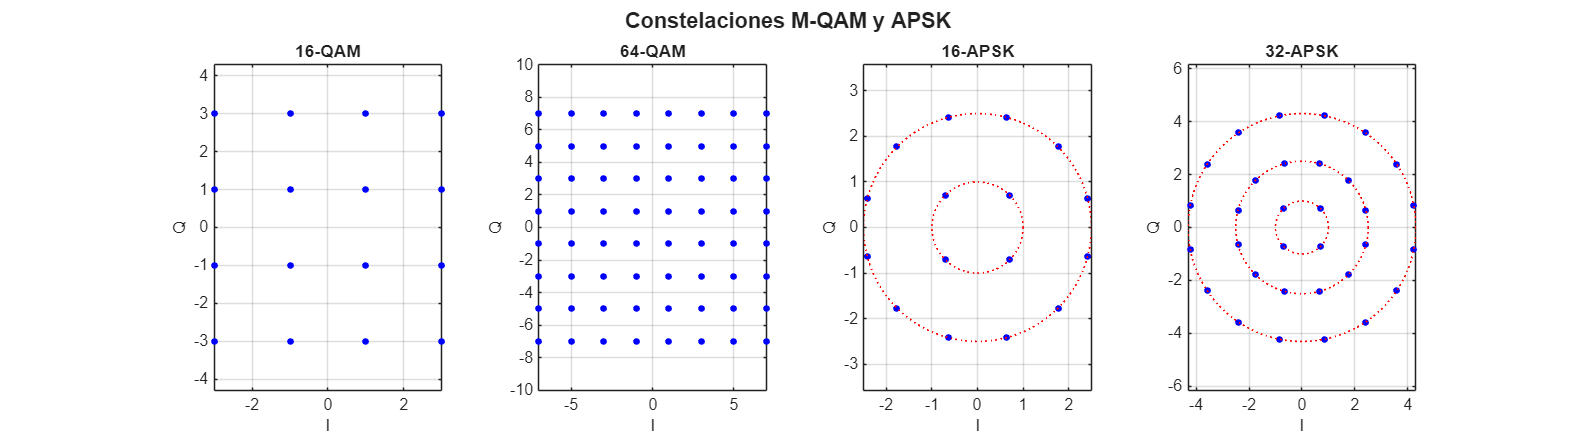


% 2. Constelaciones
figure('Color', 'w', 'Position', [40 150 1450 400]);
idx_c = [2 3 5 6];
th_c  = linspace(0, 2*pi, 200);
for j = 1:4
    i = idx_c(j);
    subplot(1, 4, j);
    plot(real(consts{i}), imag(consts{i}), 'b.', 'MarkerSize', 12); hold on;
    if i == 5, R = R_16APSK; elseif i == 6, R = R_32APSK; else, R = []; end
    for r = R
        plot(r*cos(th_c), r*sin(th_c), 'r:', 'LineWidth', 1);
    end
    grid on; axis square; axis equal;
    title(Modulacion(i), 'FontWeight', 'bold');
    xlabel('I'); ylabel('Q');
end
sgtitle('Constelaciones M-QAM y APSK', 'FontSize', 13, 'FontWeight', 'bold');

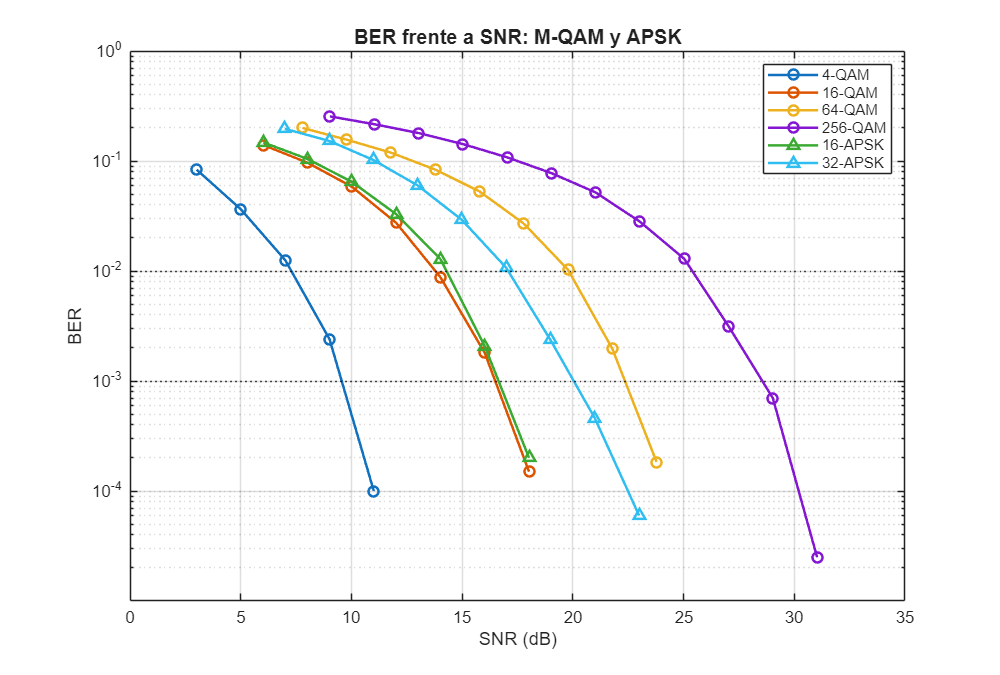


% 3. BER frente a SNR de todas las modulaciones
colores = lines(6);
marcas  = {'o-', 'o-', 'o-', 'o-', '^-', '^-'};
figure('Color', 'w', 'Position', [150 150 800 540]);
for i = 1:6
    semilogy(SNR_3(i,:), BER_3(i,:), marcas{i}, 'Color', colores(i,:), 'LineWidth', 1.5); hold on;
end
yline(1e-2, 'k:', 'HandleVisibility', 'off');
yline(1e-3, 'k:', 'HandleVisibility', 'off');
grid on; ylim([1e-5 1]);
title('BER frente a SNR: M-QAM y APSK', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('SNR (dB)', 'FontSize', 11); ylabel('BER', 'FontSize', 11);
legend(cellstr(Modulacion), 'Location', 'northeast');

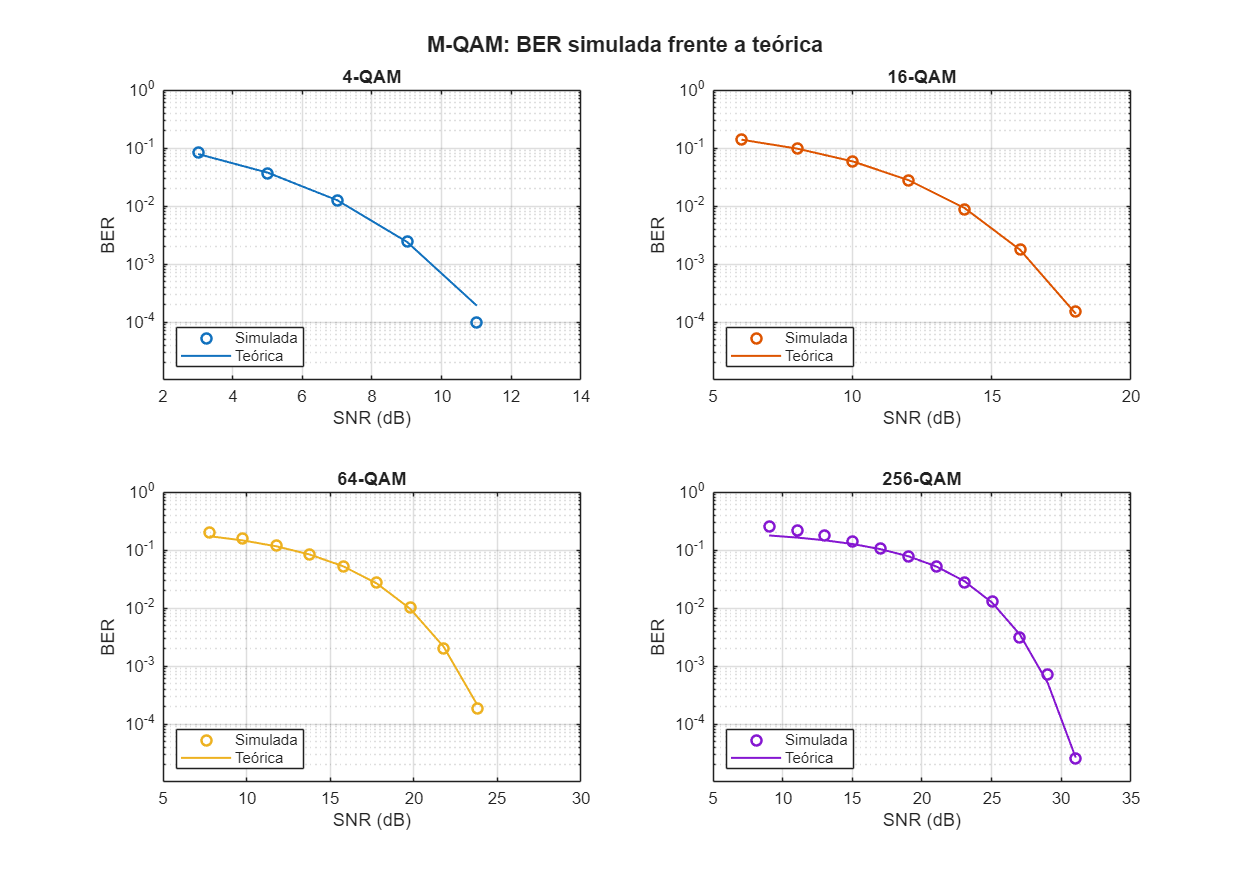


% 4. M-QAM: simulada frente a teórica
figure('Color', 'w', 'Position', [100 100 1000 700]);
for i = 1:4
    subplot(2, 2, i);
    semilogy(SNR_3(i,:), BER_3(i,:), 'o', 'Color', colores(i,:), 'LineWidth', 1.5); hold on;
    semilogy(SNR_3(i,:), BER_QAMteor(i,:), '-', 'Color', colores(i,:), 'LineWidth', 1.2);
    grid on; ylim([1e-5 1]);
    title(Modulacion(i), 'FontWeight', 'bold');
    xlabel('SNR (dB)'); ylabel('BER');
    legend({'Simulada', 'Teórica'}, 'Location', 'southwest');
end
sgtitle('M-QAM: BER simulada frente a teórica', 'FontSize', 13, 'FontWeight', 'bold');

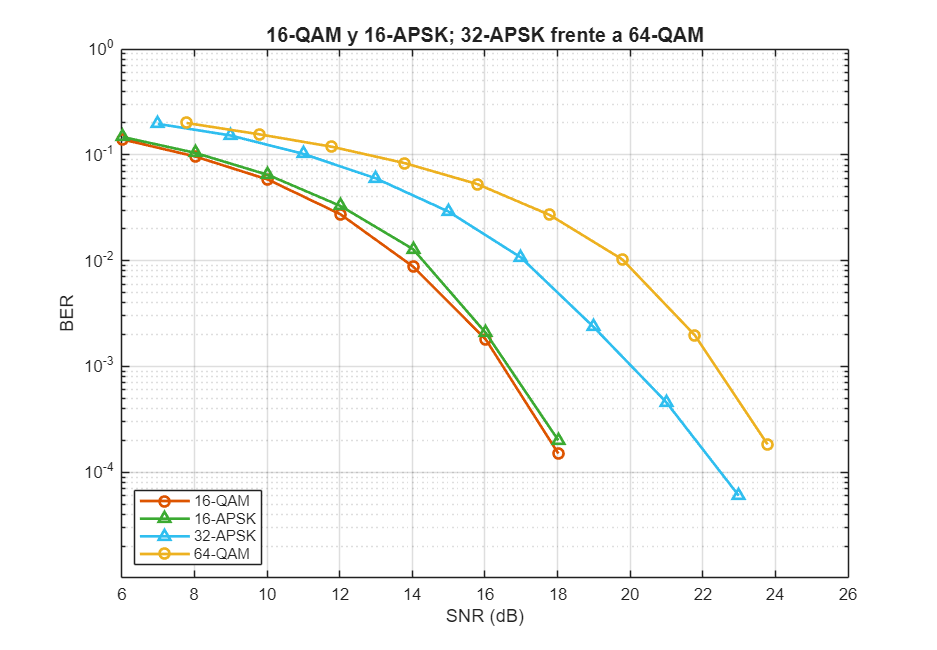


% 5. Comparación QAM frente a APSK de orden parecido
figure('Color', 'w', 'Position', [150 150 750 520]);
for i = [2 5 6 3]
    semilogy(SNR_3(i,:), BER_3(i,:), marcas{i}, 'Color', colores(i,:), 'LineWidth', 1.6); hold on;
end
grid on; ylim([1e-5 1]);
title('16-QAM y 16-APSK; 32-APSK frente a 64-QAM', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('SNR (dB)', 'FontSize', 11); ylabel('BER', 'FontSize', 11);
legend(cellstr(Modulacion([2 5 6 3])), 'Location', 'southwest');

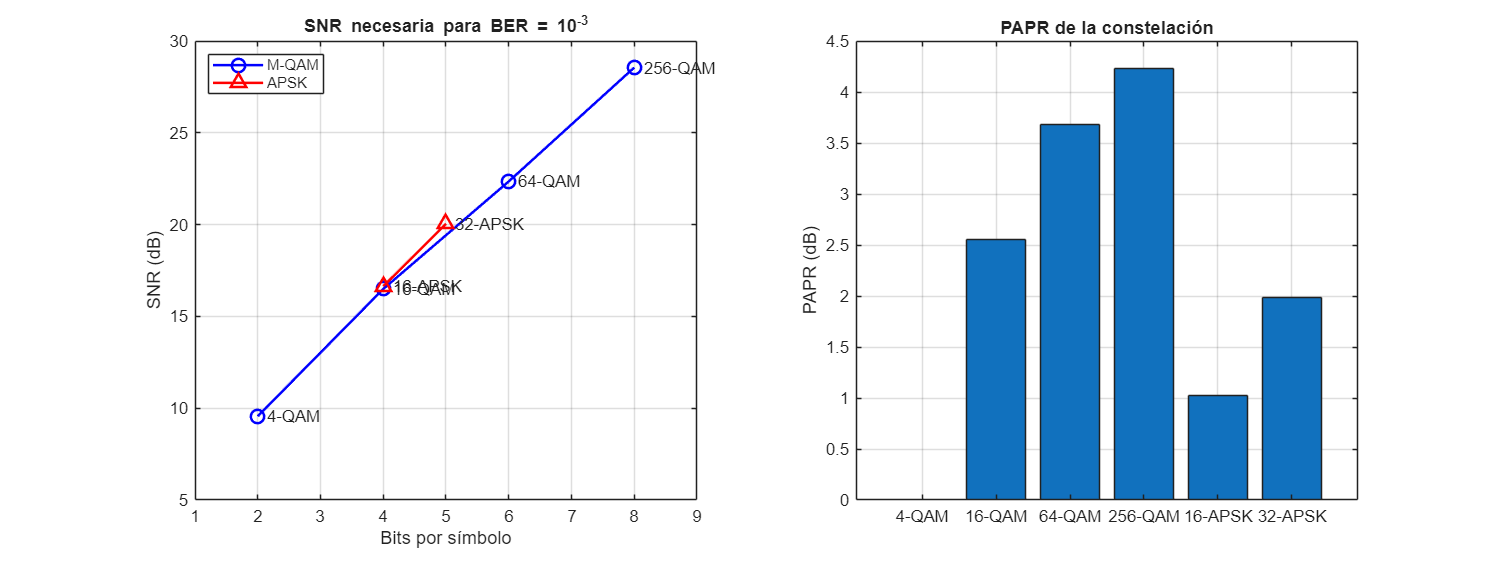


% 6. Compromiso eficiencia espectral - potencia y PAPR
figure('Color', 'w', 'Position', [100 150 1200 450]);
subplot(1, 2, 1);
plot(Bits_simb(1:4), SNR_1e3(1:4), 'bo-', 'LineWidth', 1.5, 'MarkerSize', 8); hold on;
plot(Bits_simb(5:6), SNR_1e3(5:6), 'r^-', 'LineWidth', 1.5, 'MarkerSize', 8);
text(Bits_simb + 0.15, SNR_1e3, cellstr(Modulacion));
grid on; xlim([1 9]);
title('SNR necesaria para BER = 10^{-3}', 'FontWeight', 'bold');
xlabel('Bits por símbolo'); ylabel('SNR (dB)');
legend({'M-QAM', 'APSK'}, 'Location', 'northwest');
subplot(1, 2, 2);
bar(categorical(Modulacion, Modulacion), PAPR_dB);
grid on;
title('PAPR de la constelación', 'FontWeight', 'bold');
ylabel('PAPR (dB)');